# Trabajo Practico Filtro IIR

## Ejercicio 1

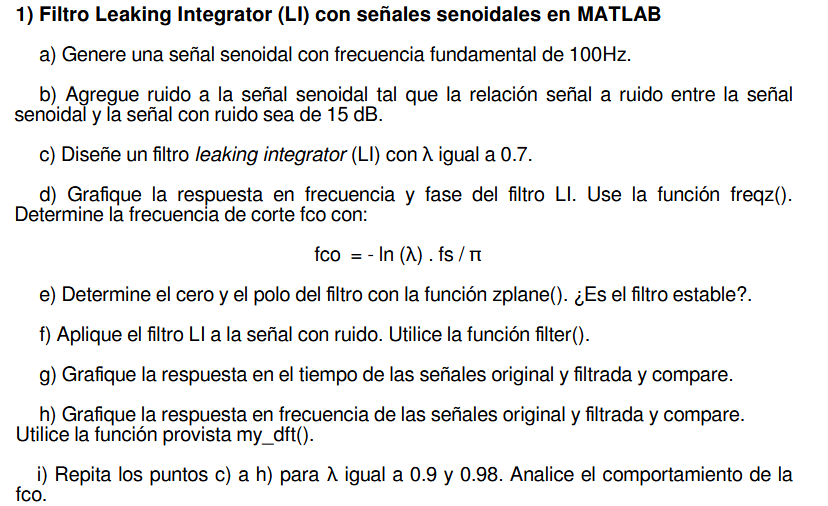

t=0:0.0001:0.1

t =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


signal = sin(2*pi*100*t);
target_snr = 15; %[dB]
noisy_signal = awgn(signal,15,"measured");

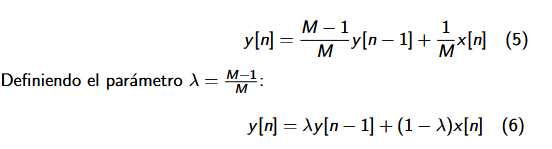

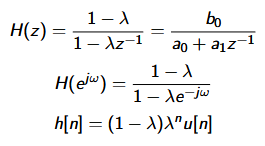

Leaky Integrator o Single Pole Filter:

lambda = 0.7;
b = 1 - lambda;
a = [1 -lambda];
filt_signal = filter(b,a,noisy_signal);
fs = 1/0.0001;
fco = - log(lambda)*fs/pi;
disp(fco);

   1.1353e+03



Respuesta en magnitud y fase del filtro:

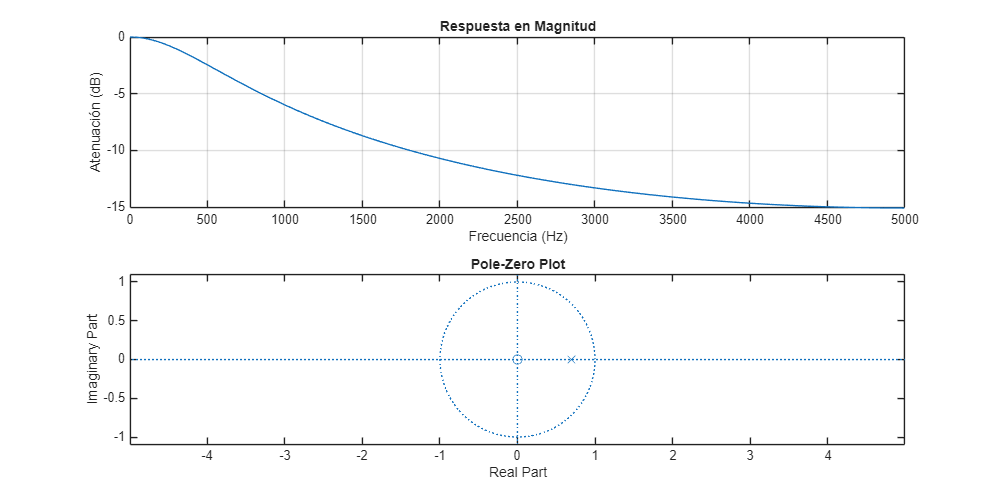

[h, f] = freqz(b, a, 1024, fs);
% Graficar Magnitud
subplot(2,1,1);
plot(f, 20*log10(abs(h)));
grid on;
title('Respuesta en Magnitud');
xlabel('Frecuencia (Hz)');
ylabel('Atenuación (dB)');
% Graficar Fase
subplot(2,1,2);
plot(f, unwrap(angle(h))*180/pi);
grid on;
title('Respuesta en Fase');
xlabel('Frecuencia (Hz)');
ylabel('Fase (grados)');
hold off;
zplane(b,a)

#### Figura 1: Comparación con lambda = 0.7 

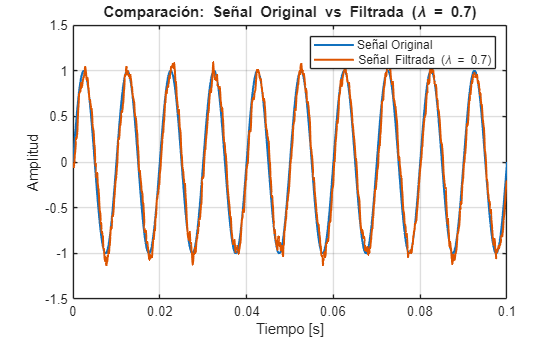

figure;
plot(t, signal, 'LineWidth', 1.5); hold on;
plot(t, filt_signal, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Comparación: Señal Original vs Filtrada (\lambda = 0.7)');
legend('Señal Original', 'Señal Filtrada (\lambda = 0.7)');
hold off;

#### Figura 2: Cálculo y comparación con lambda = 0.9

lambda_2 = 0.9;
b_2 = 1 - lambda_2;
a_2 = [1 -lambda_2];
filt_signal_2 = filter(b_2, a_2, noisy_signal);
fco_2 = - log(lambda_2)*fs/pi;
disp(fco_2);

  335.3729



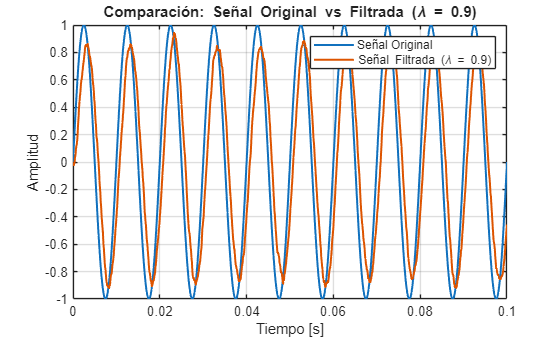

figure;
plot(t, signal, 'LineWidth', 1.5); hold on;
plot(t, filt_signal_2, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Comparación: Señal Original vs Filtrada (\lambda = 0.9)');
legend('Señal Original', 'Señal Filtrada (\lambda = 0.9)');
hold off;

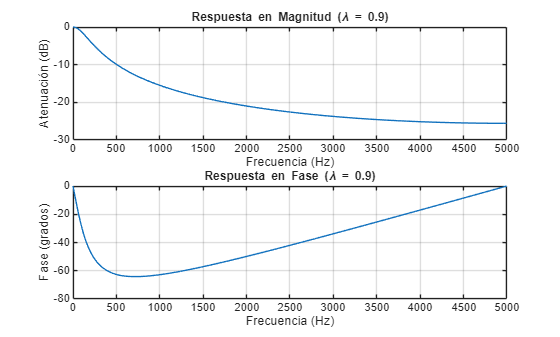

figure;
[h_2, f_2] = freqz(b_2, a_2, 1024, fs);
subplot(2,1,1);
plot(f_2, 20*log10(abs(h_2)));
grid on;
title('Respuesta en Magnitud (\lambda = 0.9)');
xlabel('Frecuencia (Hz)');
ylabel('Atenuación (dB)');

subplot(2,1,2);
plot(f_2, unwrap(angle(h_2))*180/pi);
grid on;
title('Respuesta en Fase (\lambda = 0.9)');
xlabel('Frecuencia (Hz)');
ylabel('Fase (grados)');

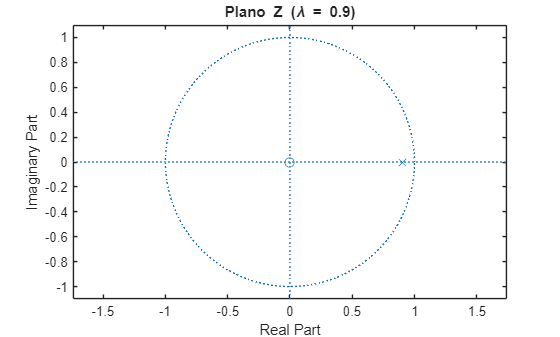


% 3. Plano Z
figure;
zplane(b_2, a_2);
title('Plano Z (\lambda = 0.9)');

#### Figura 3: Cálculo y comparación con lambda = 0.98

lambda_3 = 0.98;
b_3 = 1 - lambda_3;
a_3 = [1 -lambda_3];
filt_signal_3 = filter(b_3, a_3, noisy_signal);
fco_3 = - log(lambda_3)*fs/pi;
disp(fco_3);

   64.3072



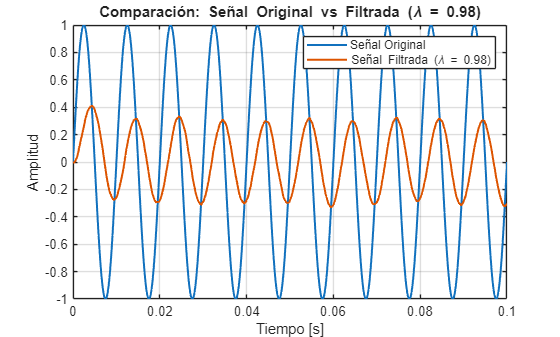

figure;
plot(t, signal, 'LineWidth', 1.5); hold on;
plot(t, filt_signal_3, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Comparación: Señal Original vs Filtrada (\lambda = 0.98)');
legend('Señal Original', 'Señal Filtrada (\lambda = 0.98)');
hold off;

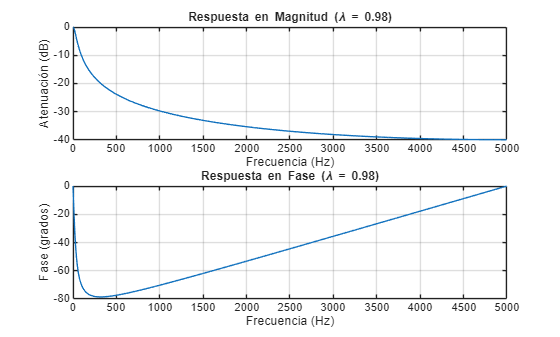

figure;
[h_3, f_3] = freqz(b_3, a_3, 1024, fs);
subplot(2,1,1);
plot(f_3, 20*log10(abs(h_3)));
grid on;
title('Respuesta en Magnitud (\lambda = 0.98)');
xlabel('Frecuencia (Hz)');
ylabel('Atenuación (dB)');

subplot(2,1,2);
plot(f_3, unwrap(angle(h_3))*180/pi);
grid on;
title('Respuesta en Fase (\lambda = 0.98)');
xlabel('Frecuencia (Hz)');
ylabel('Fase (grados)');

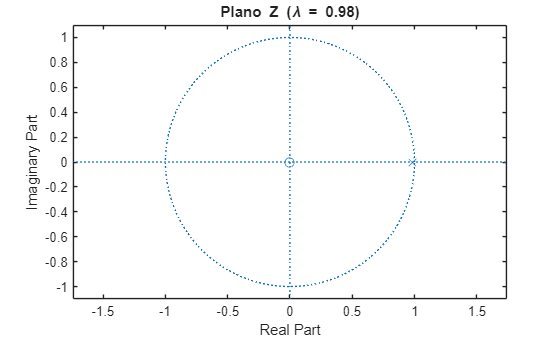


figure;
zplane(b_3, a_3);
title('Plano Z (\lambda = 0.98)');

Espectro

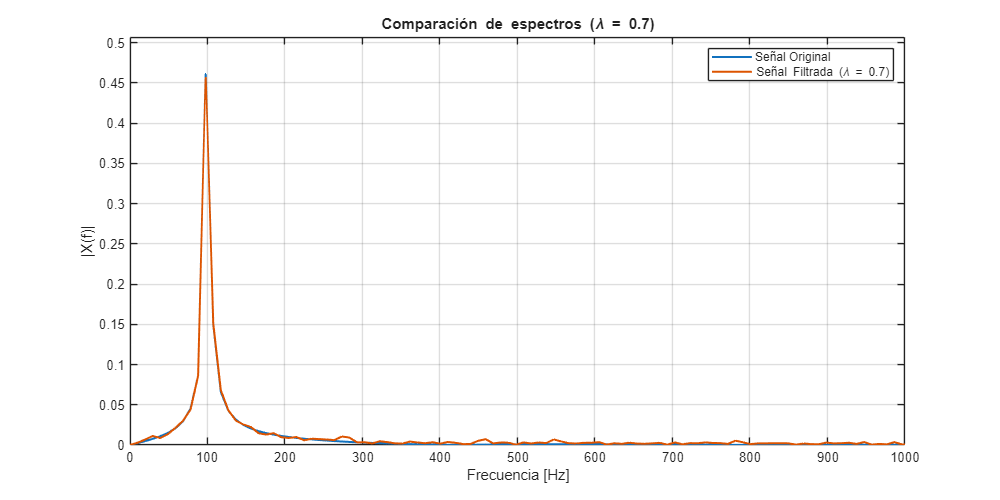

% Cálculo del espectro de la señal original
[f_orig, mag_orig, phase_orig, dft_orig, NFFT_orig] = my_dft(signal, fs);

% --- Espectro para lambda = 0.7 ---
[f_filt1, mag_filt1, phase_filt1, dft_filt1, NFFT_filt1] = my_dft(filt_signal, fs);

% Se corrige el cálculo del máximo global
y_max_1 = max([max(mag_orig), max(mag_filt1)]);

figure('Position',[100 50 1000 500]);
plot(f_orig, mag_orig, 'LineWidth', 1.5); hold on;
plot(f_filt1, mag_filt1, 'LineWidth', 1.5);
grid on;
xlim([0 fs/10]);
ylim([0 y_max_1*1.1]); % Se agrega 10% de margen superior
xlabel('Frecuencia [Hz]');
ylabel('|X(f)|');
title('Comparación de espectros (\lambda = 0.7)');
legend('Señal Original', 'Señal Filtrada (\lambda = 0.7)');
hold off;

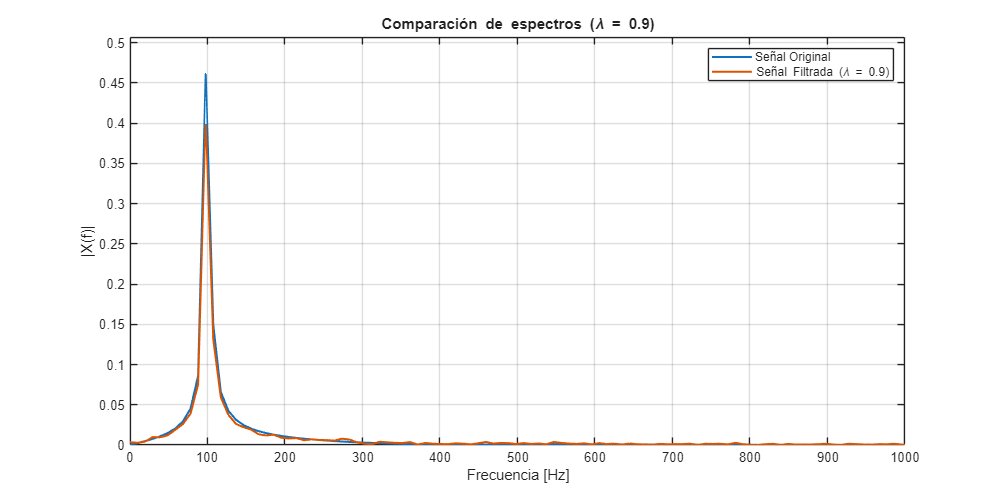


% --- Espectro para lambda = 0.9 ---
[f_filt2, mag_filt2, phase_filt2, dft_filt2, NFFT_filt2] = my_dft(filt_signal_2, fs);

y_max_2 = max([max(mag_orig), max(mag_filt2)]);

figure('Position',[100 50 1000 500]);
plot(f_orig, mag_orig, 'LineWidth', 1.5); hold on;
plot(f_filt2, mag_filt2, 'LineWidth', 1.5);
grid on;
xlim([0 fs/10]);
ylim([0 y_max_2*1.1]);
xlabel('Frecuencia [Hz]');
ylabel('|X(f)|');
title('Comparación de espectros (\lambda = 0.9)');
legend('Señal Original', 'Señal Filtrada (\lambda = 0.9)');
hold off;

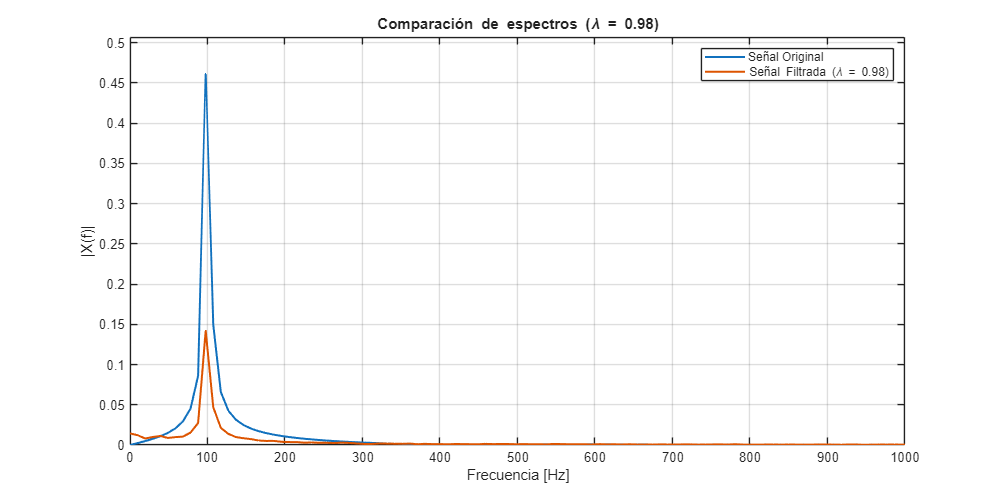


% --- Espectro para lambda = 0.98 ---
[f_filt3, mag_filt3, phase_filt3, dft_filt3, NFFT_filt3] = my_dft(filt_signal_3, fs);

y_max_3 = max([max(mag_orig), max(mag_filt3)]);

figure('Position',[100 50 1000 500]);
plot(f_orig, mag_orig, 'LineWidth', 1.5); hold on;
plot(f_filt3, mag_filt3, 'LineWidth', 1.5);
grid on;
xlim([0 fs/10]);
ylim([0 y_max_3*1.1]);
xlabel('Frecuencia [Hz]');
ylabel('|X(f)|');
title('Comparación de espectros (\lambda = 0.98)');
legend('Señal Original', 'Señal Filtrada (\lambda = 0.98)');
hold off;

### Ejercicio 2

load("Tchaikovsky.mat");
target_snr = 60; %[dB]
orig_signal = signal(:,1);
t=linspace(0,0.5,length(orig_signal));
noisy_signal = awgn(orig_signal,target_snr,"measured");

Leaky Integrator o Single Pole Filter:

lambda = 0.7;
b = 1 - lambda;
a = [1 -lambda];
filt_signal = filter(b,a,noisy_signal);
fs = Fs;
fco = - log(lambda)*fs/pi;
disp(fco);

   5.0068e+03



Respuesta en magnitud y fase del filtro:

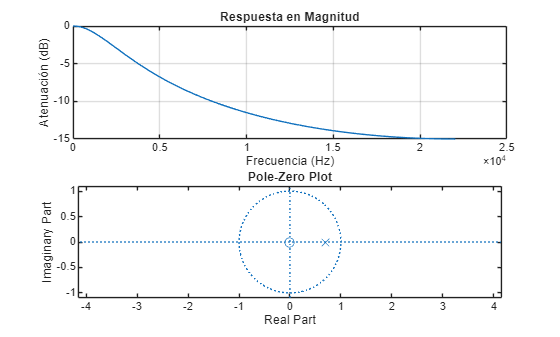

[h, f] = freqz(b, a, 1024, fs);
% Graficar Magnitud
subplot(2,1,1);
plot(f, 20*log10(abs(h)));
grid on;
title('Respuesta en Magnitud');
xlabel('Frecuencia (Hz)');
ylabel('Atenuación (dB)');
% Graficar Fase
subplot(2,1,2);
plot(f, unwrap(angle(h))*180/pi);
grid on;
title('Respuesta en Fase');
xlabel('Frecuencia (Hz)');
ylabel('Fase (grados)');
hold off;
zplane(b,a)

#### Figura 1: Comparación con lambda = 0.7 

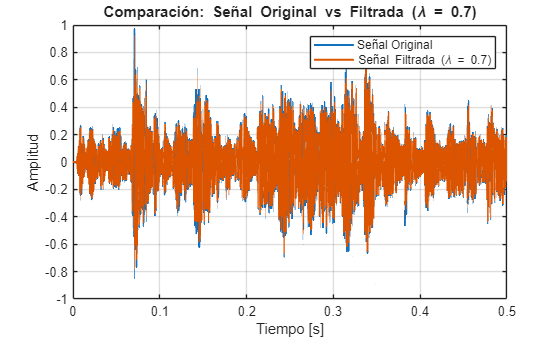

figure;
plot(t, orig_signal, 'LineWidth', 1.5); hold on;
plot(t, filt_signal, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Comparación: Señal Original vs Filtrada (\lambda = 0.7)');
legend('Señal Original', 'Señal Filtrada (\lambda = 0.7)');
hold off;

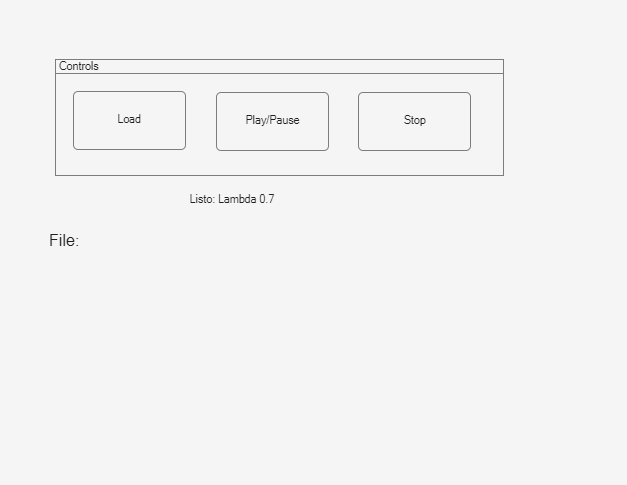

pruebasonido(filt_signal,Fs,"Lambda 0.7");

#### Figura 2: Cálculo y comparación con lambda = 0.9

lambda_2 = 0.9;
b_2 = 1 - lambda_2;
a_2 = [1 -lambda_2];
filt_signal_2 = filter(b_2, a_2, noisy_signal);
fco_2 = - log(lambda_2)*fs/pi;
disp(fco_2);

   1.4790e+03



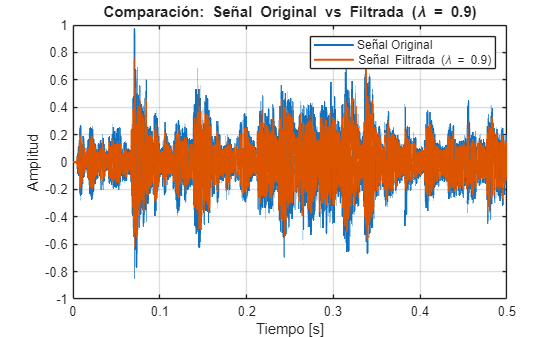

figure;
plot(t, orig_signal, 'LineWidth', 1.5); hold on;
plot(t, filt_signal_2, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Comparación: Señal Original vs Filtrada (\lambda = 0.9)');
legend('Señal Original', 'Señal Filtrada (\lambda = 0.9)');
hold off;

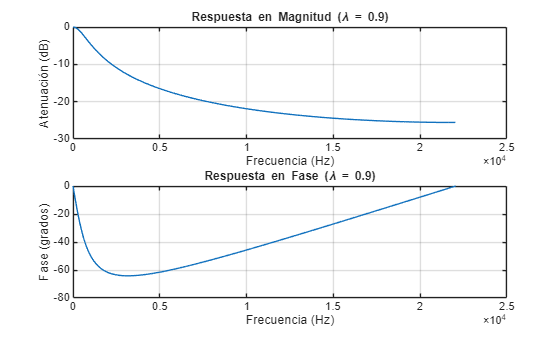

figure;
[h_2, f_2] = freqz(b_2, a_2, 1024, fs);
subplot(2,1,1);
plot(f_2, 20*log10(abs(h_2)));
grid on;
title('Respuesta en Magnitud (\lambda = 0.9)');
xlabel('Frecuencia (Hz)');
ylabel('Atenuación (dB)');

subplot(2,1,2);
plot(f_2, unwrap(angle(h_2))*180/pi);
grid on;
title('Respuesta en Fase (\lambda = 0.9)');
xlabel('Frecuencia (Hz)');
ylabel('Fase (grados)');


% 3. Plano Z
figure;
zplane(b_2, a_2);
title('Plano Z (\lambda = 0.9)');

pruebasonido(filt_signal_2,Fs,"Lambda 0.9");

#### Figura 3: Cálculo y comparación con lambda = 0.98

lambda_3 = 0.98;
b_3 = 1 - lambda_3;
a_3 = [1 -lambda_3];
filt_signal_3 = filter(b_3, a_3, noisy_signal);
fco_3 = - log(lambda_3)*fs/pi;
disp(fco_3);

  283.5948



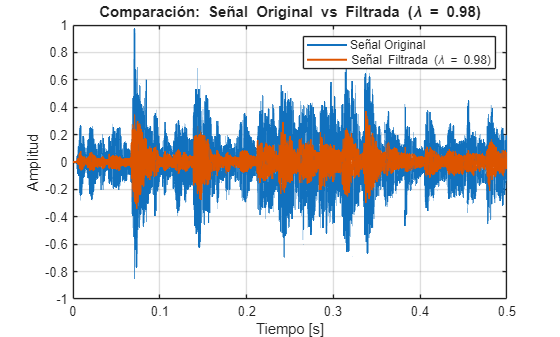

figure;
plot(t, orig_signal, 'LineWidth', 1.5); hold on;
plot(t, filt_signal_3, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Comparación: Señal Original vs Filtrada (\lambda = 0.98)');
legend('Señal Original', 'Señal Filtrada (\lambda = 0.98)');
hold off;

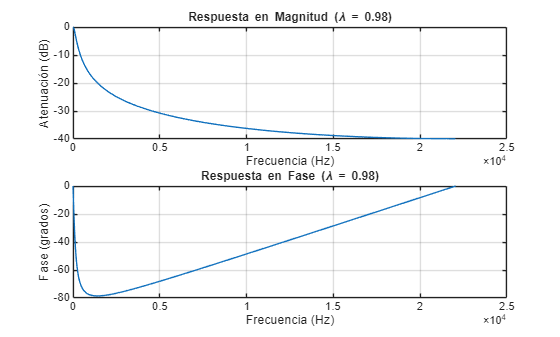

figure;
[h_3, f_3] = freqz(b_3, a_3, 1024, fs);
subplot(2,1,1);
plot(f_3, 20*log10(abs(h_3)));
grid on;
title('Respuesta en Magnitud (\lambda = 0.98)');
xlabel('Frecuencia (Hz)');
ylabel('Atenuación (dB)');

subplot(2,1,2);
plot(f_3, unwrap(angle(h_3))*180/pi);
grid on;
title('Respuesta en Fase (\lambda = 0.98)');
xlabel('Frecuencia (Hz)');
ylabel('Fase (grados)');


figure;
zplane(b_3, a_3);
title('Plano Z (\lambda = 0.98)');

pruebasonido(filt_signal_3,Fs,"Lambda 0.98");
filtered_signals = {filt_signal, filt_signal_2, filt_signal_3};
etiquetas = {"\lambda = 0.7","\lambda = 0.9","\lambda = 0.98"};

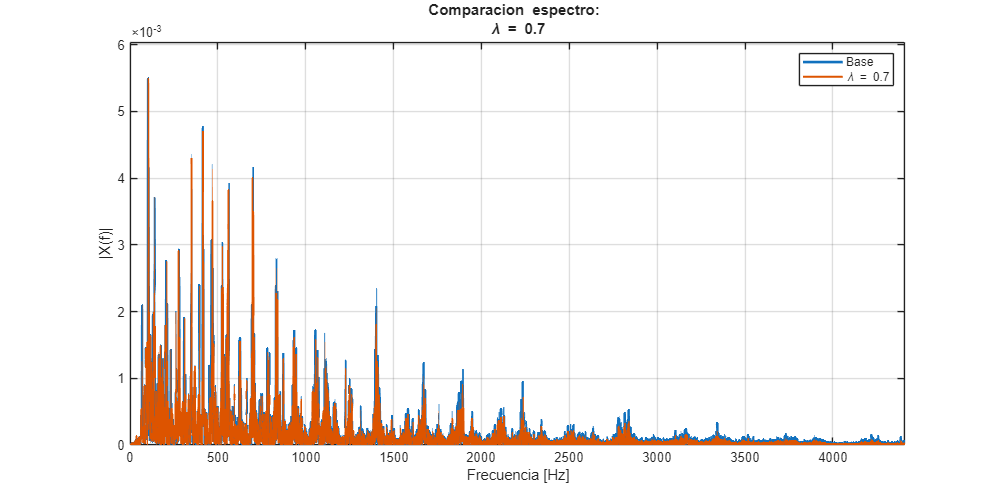

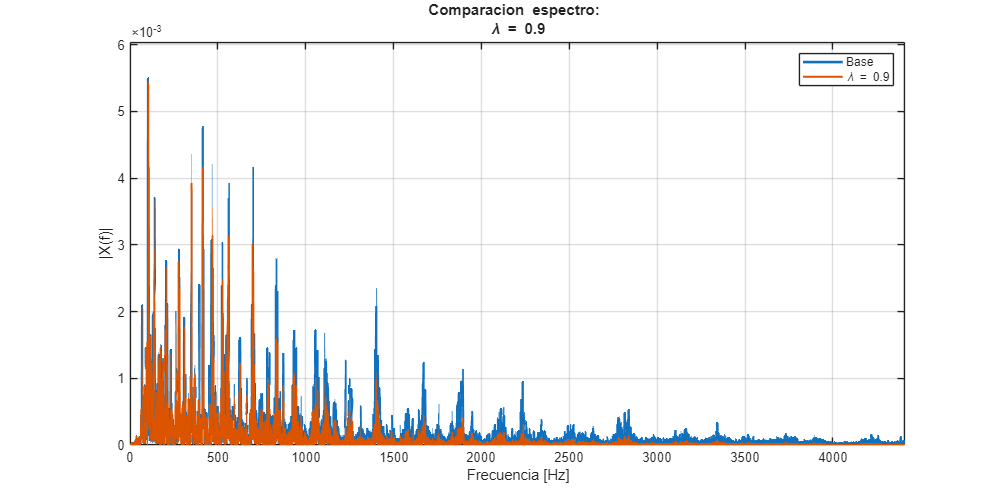

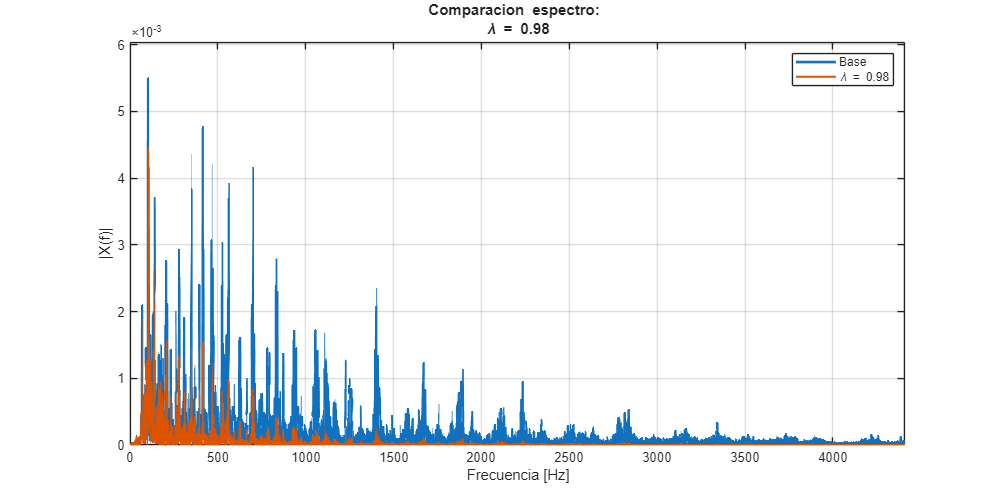

comparar_espectros('base',orig_signal,'compare_to',filtered_signals,'fs',fs,'lim_x',fs/10,'labels',etiquetas);

### Ejercicio 3